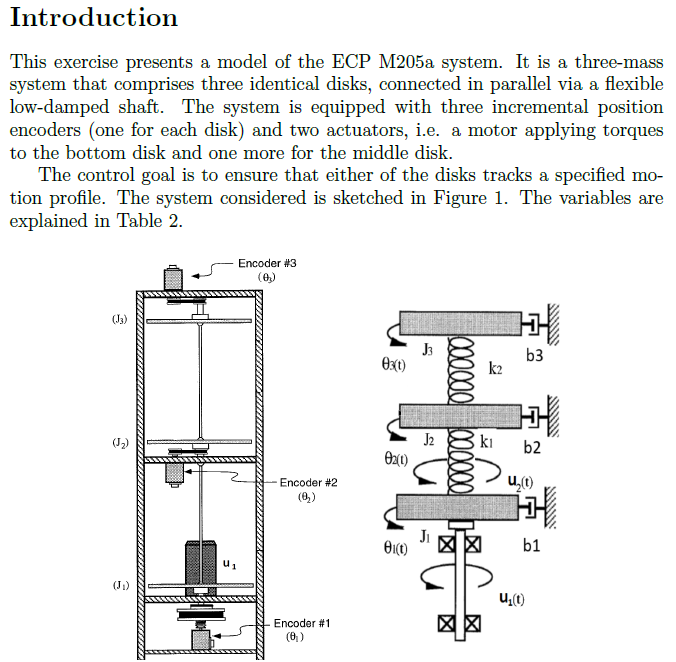

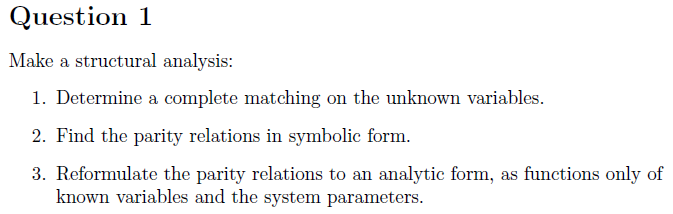

clear all;
clc;
addpath("C:\Users\botto\OneDrive\Backup\Bertram lenovo\DTU\34746 Robust and Fault-tolerant Control\Exercise\SA Tool\SaTool_3_0100\sa_tool_3_0100\");

%syms Theta_1 Theta_2 Theta_3 omega_1 omega_2 omega_3 u1 u2 y1 y2 y3

% List of Parameters
J_1 = 0.0025; %Bottom disk moment of inertia
J_2 = 0.0018; %Middle disk moment of inertia
k_1 = 2.7; %Stiffness of the bottom shaft
k_2 = 2.6; %Stiffness of the middle shaft
b_1 = 0.0029; %Damping/friction on the bottom disk
b_2 = 0.0002; %Damping/friction on the middle disk
b_3 = 0.00015; %Damping/friction on the top disk

%0 = Theta_1 - omega_1;
%0 = J_1*omega_1dot - u_1 + b_1*omega_1 + k1*(Theta_1 - Theta_2) + d;
%0 = Theta_2dot - omega_2;
%0 = J_2_omega_2dot - u_2 + b_2*omega_2 + k_1*(Theta_2 - Theta_1) + k_2*(Theta_2 - Theta_3);
%0 = Theta_3dot - omega_3;
%0 = J_3*omega_3dot + b_3*omega_3 + k_2*(Theta_3 - Theta_2)
%0 = Theta_1dot - diff(Theta_1,t);
%0 = omega_1dot - diff(omega_1,t);
%0 = Theta_2dot - diff(Theta_2,t);
%0 = omega_2dot - diff(omega_2,t);
%0 = Theta_3dot - diff(Theta_3,t);
%0 = omega_3dot - diff(omega_3,t);
%0 = y_1 - Theta_1;
%0 = y_2 - Theta_2;
%0 = y_3 - Theta_3;



SA Tool

% Inputs
syms u_1(t) u_2(t) % Symbolic input declearation
ST_input(1,:) = {u_1,u_2}; % symbolic variable
ST_input(2,:) = {'u_1(t)','u_2(t)'}; % LaTeX expression


% Measurements
syms y_1(t) y_2(t) y_3(t) % Symbolic measurement declearation
ST_meas(1,:) = {y_1,y_2,y_3}; % symbolic variable
ST_meas(2,:) = {'y_1(t)','y_2(t)','y_3(t)'}; % LaTeX expression


% Unknowns
syms Theta_1(t) dTheta_1(t) omega_1(t) domega_1(t) Theta_2(t) dTheta_2(t) omega_2(t) domega_2(t) Theta_3(t) dTheta_3(t) omega_3(t) domega_3(t) d % Symbolic unknowns declearation
ST_unknowns(1,:) = {Theta_1, dTheta_1, omega_1, domega_1, Theta_2, dTheta_2, omega_2, domega_2, Theta_3, dTheta_3, omega_3, domega_3, d}; % symbolic variable
ST_unknowns(2,:) = {'theta_1', 'dtheta_1', 'omega_1', 'domega_1', 'theta_2', 'dtheta_2', 'omega_2', 'domega_2', 'theta_3', 'dtheta_3', 'omega_3', 'domega_3', 'd'}; % LaTeX expression


% Parameters
syms J_1 J_2 J_3 k_1 k_2 b_1 b_2 b_3 % Symbolic parameter declearation
ST_parameters(1,:) = {J_1, J_2, J_3, k_1, k_2, b_1, b_2, b_3}; % symbolic variable
ST_parameters(2,:) = {'J_1', 'J_2', 'J_3', 'k_1', 'k_2', 'b_1', 'b_2', 'b_3'};% LaTeX expression


ST_cons(1,:) = {'c1','c2', 'c3','c4','c5','c6','m13','m14','m15','d7','d8', 'd9','d10','d11', 'd12'};
ST_cons(2,:) = {'c_1','c_2', 'c_3','c_4','c_5','c_6','m_{13}','m_{14}','m_{15}','d_7','d_8', 'd_9','d_{10}','d_{11}', 'd_{12}'};     % LaTeX   
ST_cons(3,:) = {...
    0 == dTheta_1 - omega_1, ...
    0 == J_1*domega_1 - u_1 + b_1*omega_1 + k_1*(Theta_1 - Theta_2) + d, ...
    0 == dTheta_2 - omega_2, ...
    0 == J_2 * domega_2 - u_2 + b_2*omega_2 + k_1*(Theta_2 - Theta_1) + k_2*(Theta_2 - Theta_3), ...
    0 == dTheta_3 - omega_3, ...
    0 == J_3*domega_3 + b_3*omega_3 + k_2*(Theta_3 - Theta_2), ...
    0 == y_1 - Theta_1, ...
    0 == y_2 - Theta_2, ...
    0 == y_3 - Theta_3, ...
    0 == dTheta_1 - diff(Theta_1,t), ...
    0 == domega_1 - diff(omega_1,t), ...
    0 == dTheta_2 - diff(Theta_2,t), ...
    0 == domega_2 - diff(omega_2,t), ...
    0 == dTheta_3 - diff(Theta_3,t), ...
    0 == domega_3 - diff(omega_3,t)};

    ST_canfail = [1:9];

    %husk {} omkring causale parameter, (differential)
    cons_oneway = {[],[],[],[],[],[],[],[],[],{Theta_1},{omega_1},{Theta_2},{omega_2},{Theta_3},{omega_3}};
    ST_domains = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];

    ST_IncMat = sa_incidencematrix(ST_cons,ST_input,ST_meas,ST_unknowns,cons_oneway)

    % create system
ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail,ST_parameters)

% Find matchings
ST_sys=sa_match(ST_sys,'rank')

% Create report
% sa_report(ST_sys,'Assignment_A','pdf','analytic_expressions',true); 

% Create  matching
disp('Obtained matching:');
sa_disp(ST_sys, 't');

% Create Symbolic form
disp('Parity relation symbolic form:')
sa_disp(ST_sys, 's');

% Create analytical form
disp('Parity relation analytic form:')
sa_disp(ST_sys, 'a');

% Analystisk form in Laplase
syms s
syms y_1 y_2 y_3
syms u_1 u_2
a1 = (u_2 - b_2*y_2*s + k_1*y_1 - k_1*y_2 - k_2*y_2 + k_2*y_3)/J_2 - y_2*s^2;
a2 = (k_2*(y_2 - y_3) - b_3*y_3*s)/J_3 - y_3*s^2;

syms lambda

a1-lambda*a2
% Define lambda
solve(0==k_2/J_2+(lambda*k_2)/J_3+(lambda*b_3*s)/J_3-lambda*s^(2),lambda)
lambda = - (J_3*k_2) / (J_2*J_3*s^2 - J_2*b_3*s + J_2*k_2);

% Compute a3 = a1 - lambda * a2
a3 = simplify(a1 - lambda * a2);

% Solve for y3 in terms of other variables
y3_expr = solve(a2, y_3);

% Substitute y3 into a3 to eliminate it
a3_no_y3 = simplify(subs(a3, y_3, y3_expr));
a3 = a3_no_y3
disp('Simplified a3 without y3:');
disp(a3);




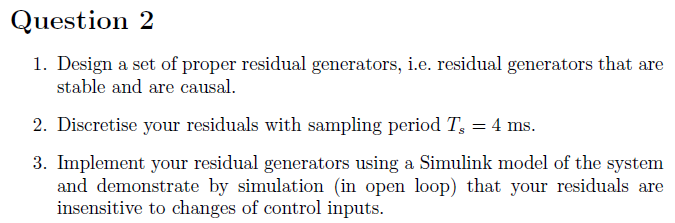

wn = 15;  % Cutoff frequency (rad/s), chosen below the system's resonant frequencies
zeta = 0.707;  % Damping ratio (Butterworth design)

% Define second-order low-pass filter
s = tf('s');
H = (wn^2) / (s^2 + 2*zeta*wn*s + wn^2);
% Display the transfer function
disp('Adjusted Second-Order Low-Pass Filter Transfer Function:');
H


%having [r1, r2]' = Hy*[y1,y2,y3]' + Hu*[u1,u2]'
% List of Parameters
J_1 = 0.0025; %Bottom disk moment of inertia
J_2 = 0.0018; %Middle disk moment of inertia
J_3 = 0.001; %adjust just something random we imagined !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
k_1 = 2.7; %Stiffness of the bottom shaft
k_2 = 2.6; %Stiffness of the middle shaft
b_1 = 0.0029; %Damping/friction on the bottom disk
b_2 = 0.0002; %Damping/friction on the middle disk
b_3 = 0.00015; %Damping/friction on the top disk

H_ry = [k_1/J_2 (-k_1-k_2-b_2*s-J_2*s^2)/J_2 k_2/J_2; ...
   0 k_2/J_3 (-k_2-b_3*s-s^2*J_3)/J_3]
H_ru = [0 tf(1); 0 0]

sys_y = H*H_ry
sys_u = H*H_ru

sys = sys_u+sys_u
Ts = 4e-3; % Sampling period (4 ms)
dsys = c2d(sys,Ts, 'zoh')

figure;
step(R1_disc);
title('Step Response of Discretized Residual System');
xlabel('Time (seconds)');
ylabel('Response');
grid on;


%Residuals should be (by design)
%Causal (output depends only on past & present inputs)
%Stable (bounded inputs give bounded outputs)

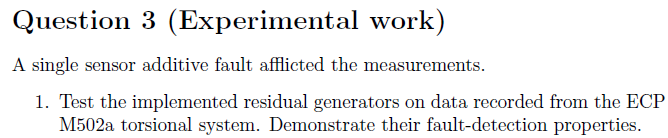

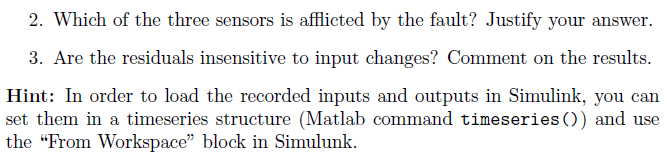

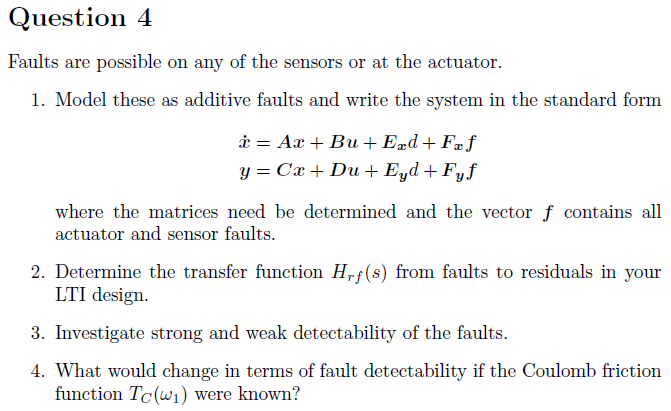

Hints: For this task it is useful to find a basis for the left nullspace by using the

Matlab symbolic toolbox in defining the various transfer functions (e.g. syms

s; G = 1/(s + 1)). You may find the following functions useful:

� simplify - simplifies symbolic expression,

� expand - expands symbolic expression,

� numden - extracts enumerator and denominator of symbolic fraction,

� sym2poly - converts symbolic polynomial to numeric,

� minreal - gives a minimal realization of a transfer function,

� zpk - expresses a transfer function as a zero-pole-gain product.